Homework #09

## 1

clear all
X=[-3.6, 1.8, -7.2, -9.6, 0.5, -0.9, -2.1, -2.8, -3.2, -2.2, 1.3, -3.6, -6.3, -0.9, -2.4, 5.2;
7.8, -7.5, -0.6, 4.5, 0.9, 0, -7, -6.8, -6.4, -9.3, -5.9, -2.5, -7.9, -6.1, 8.6, 5.4];
y=[ 1, -1, 1, 1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, 1, 1];

1a)

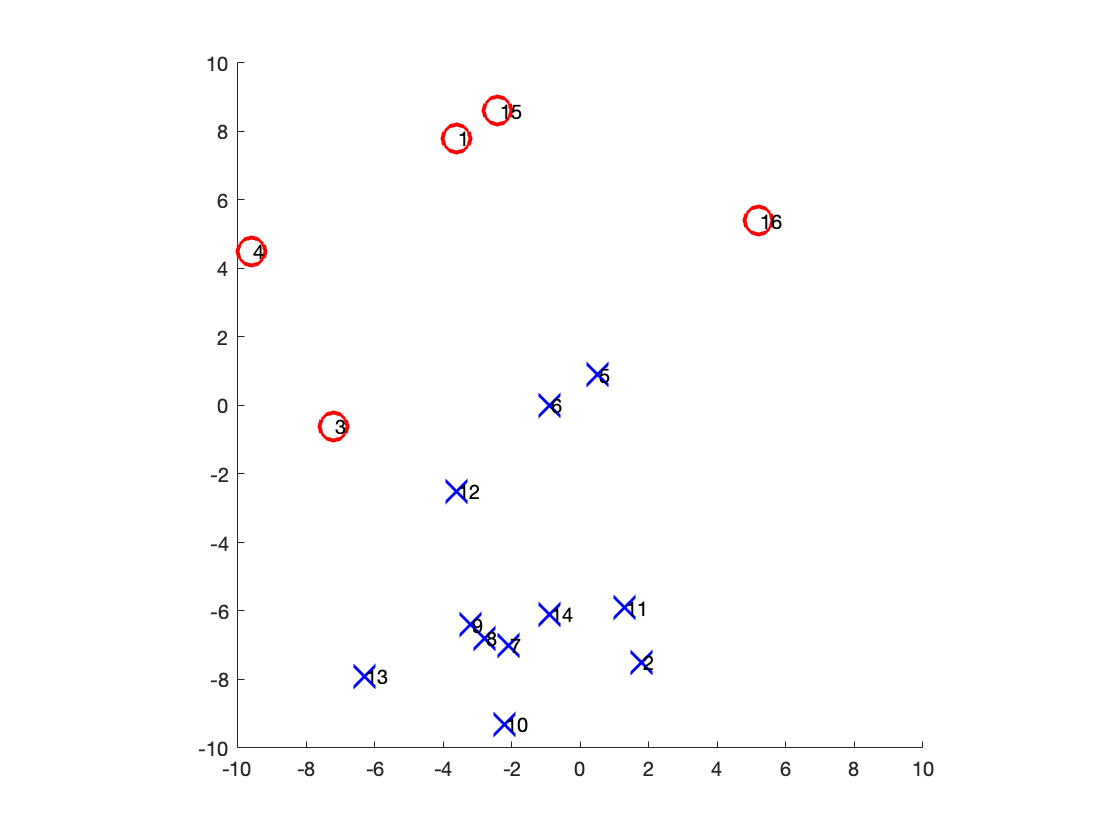

[dim, N]=size(X);

% plot training data:
sym(1:N)='o';
sym(y<0)='x';
col(1:N)='r';
col(y<0)='b';
figure;clf;hold on
for i=1:1:N
  plot(X(1,i),X(2,i),[col(i) sym(i)],'markersize',14,'linewidth',2);
  if N<=30; text(X(1,i)+0.05,X(2,i),num2str(i)); end
end
xlim([-10 10]);ylim([-10 10]);
axis square; hold off

1b)

try slightly below line between 16 and 3:

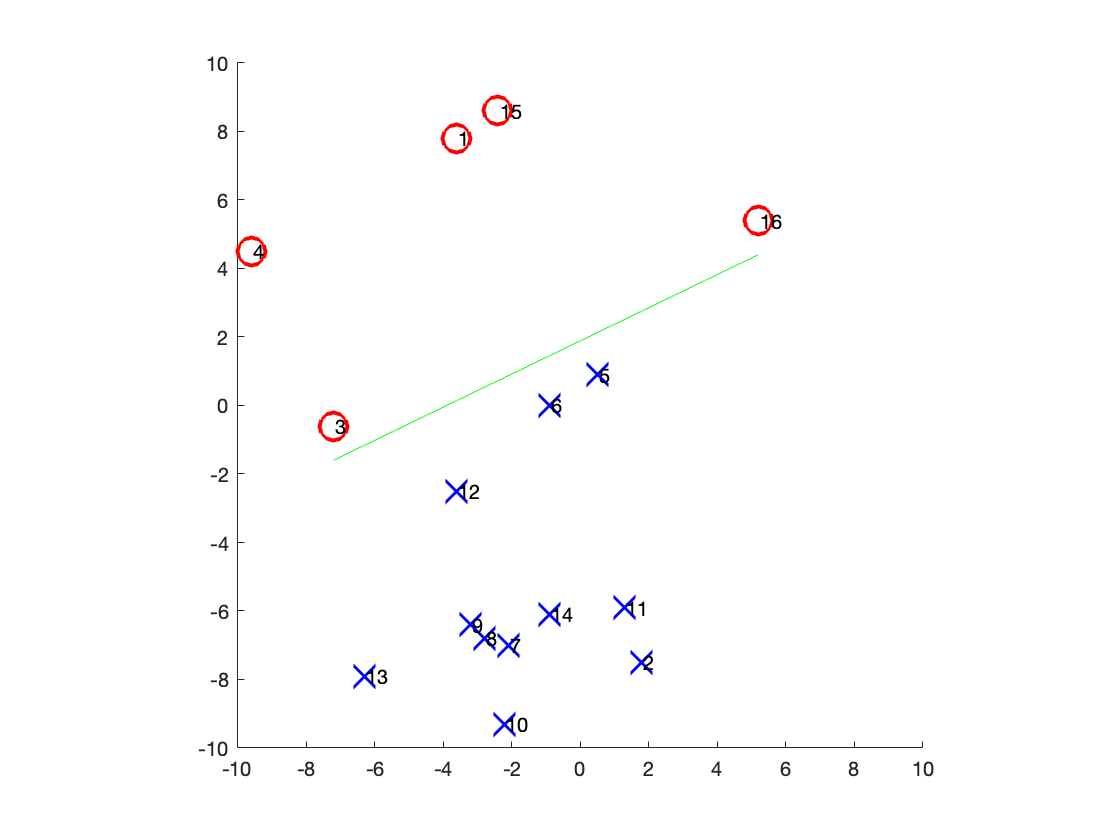

figure;clf;hold on
for i=1:1:N
  plot(X(1,i),X(2,i),[col(i) sym(i)],'markersize',14,'linewidth',2);
  if N<=30; text(X(1,i)+0.05,X(2,i),num2str(i)); end
end
xlim([-10 10]);ylim([-10 10]);
axis square;
plot([X(1,16) X(1,3)], [X(2,16)-1 X(2,3)-1], 'g')
hold off

line_fit = polyfit([X(1,16); X(1,3)], [X(2,16)-1; X(2,3)-1], 1)

line_fit =     0.4839    1.8839


w=[-1*line_fit(1); 1; line_fit(2)]

w =    -0.4839
    1.0000
    1.8839


try another one even more slightly below that one:

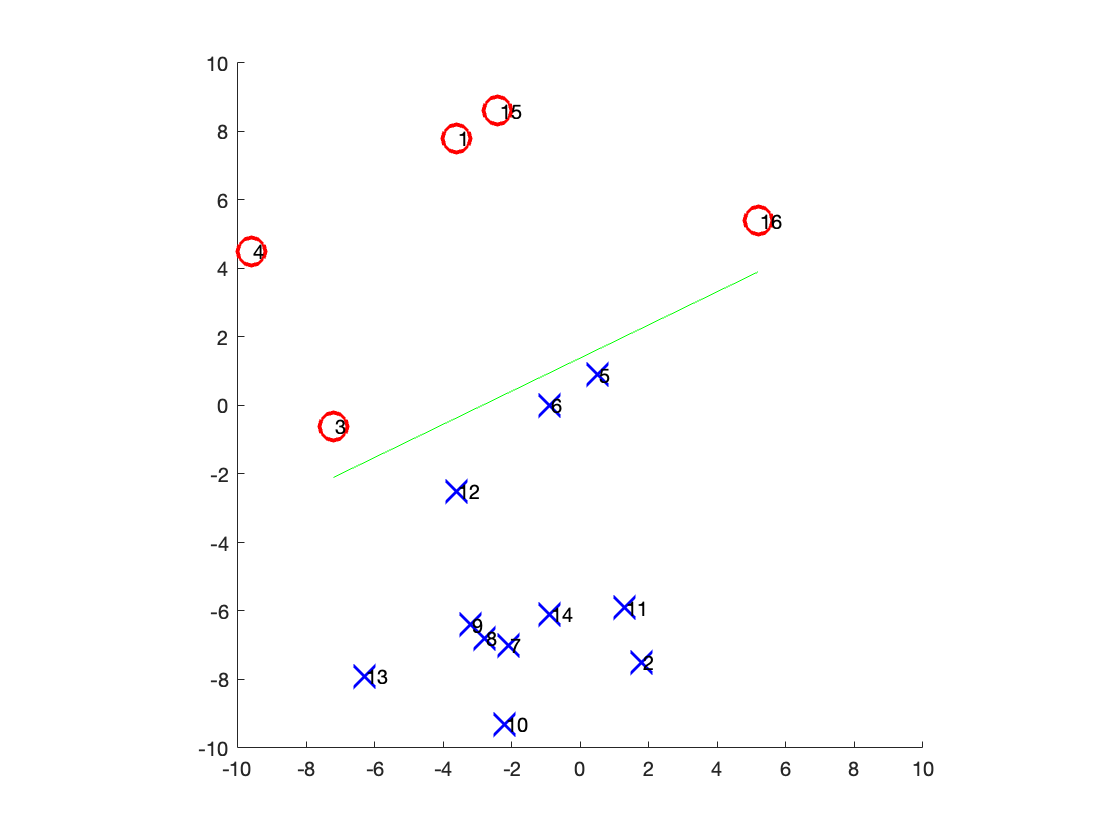

figure;clf;hold on
for i=1:1:N
  plot(X(1,i),X(2,i),[col(i) sym(i)],'markersize',14,'linewidth',2);
  if N<=30; text(X(1,i)+0.05,X(2,i),num2str(i)); end
end
xlim([-10 10]);ylim([-10 10]);
axis square;
plot([X(1,16) X(1,3)], [X(2,16)-1.5 X(2,3)-1.5], 'g')
hold off

line_fit = polyfit([X(1,16); X(1,3)], [X(2,16)-1.5; X(2,3)-1.5], 1)

line_fit =     0.4839    1.3839


w=[-1*line_fit(1); 1; line_fit(2)]

w =    -0.4839
    1.0000
    1.3839


It looks like you can put a lot of lines between the two groups because they are distinct enough. So there are an infinite number of perceptron lines that will successfully divide these groups.

1c)

small_X = X(:,[6,10,16])

small_X =    -0.9000   -2.2000    5.2000
         0   -9.3000    5.4000


small_y = y([6,10,16])

small_y =     -1    -1     1


[pic of hand calc]

1d) Adapted from "perceptron_classification_example.m"

Parameters:

eta = 0.1; % learning rate
num_epochs = 4;  % number of training loop iterations

Initialize:

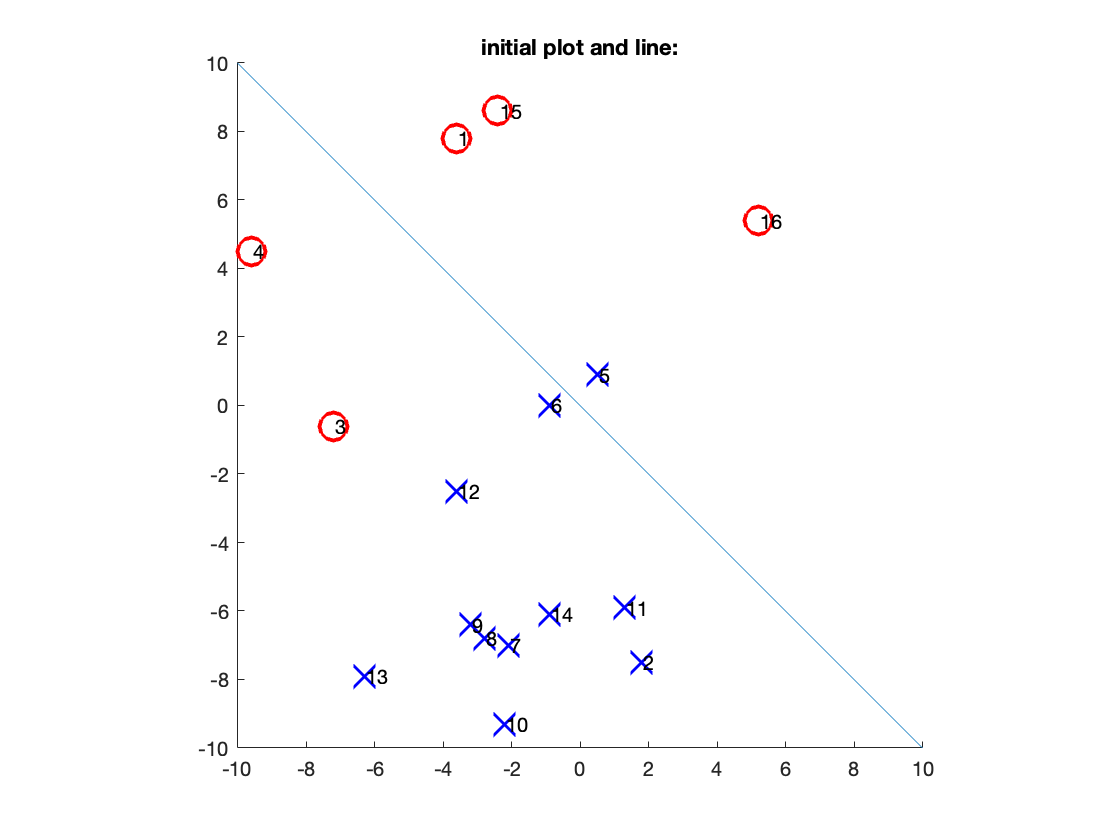

% initialize w
w=ones(dim+1,1);
theta=0;

% initialize for plotting purposes:
hl_previous.MarkerSize=0; 
harrow_previous=0;

% initial plot line
figure;clf;hold on; title('initial plot and line:')
for i=1:1:N
  plot(X(1,i),X(2,i),[col(i) sym(i)],'markersize',14,'linewidth',2);
  if N<=30; text(X(1,i)+0.05,X(2,i),num2str(i)); end
end
xlim([-10 10]);ylim([-10 10]);
axis square
% two x values to use only for plotting perceptron line, no need to change:
line_lim=[-10,10]; 
% plot initial separation line from w:
hl=plot(line_lim,(-line_lim*w(1)+theta)/w(2),'-');
hold off

Training loop:

 testing data X(:,3)=[-7.20,-0.60]; y'=-8.8; sign(y')=-1, sign(y(i))=1


adjusted from w=[   1,   1]; theta=0.00; to w=[0.21,0.71]; theta=0.68


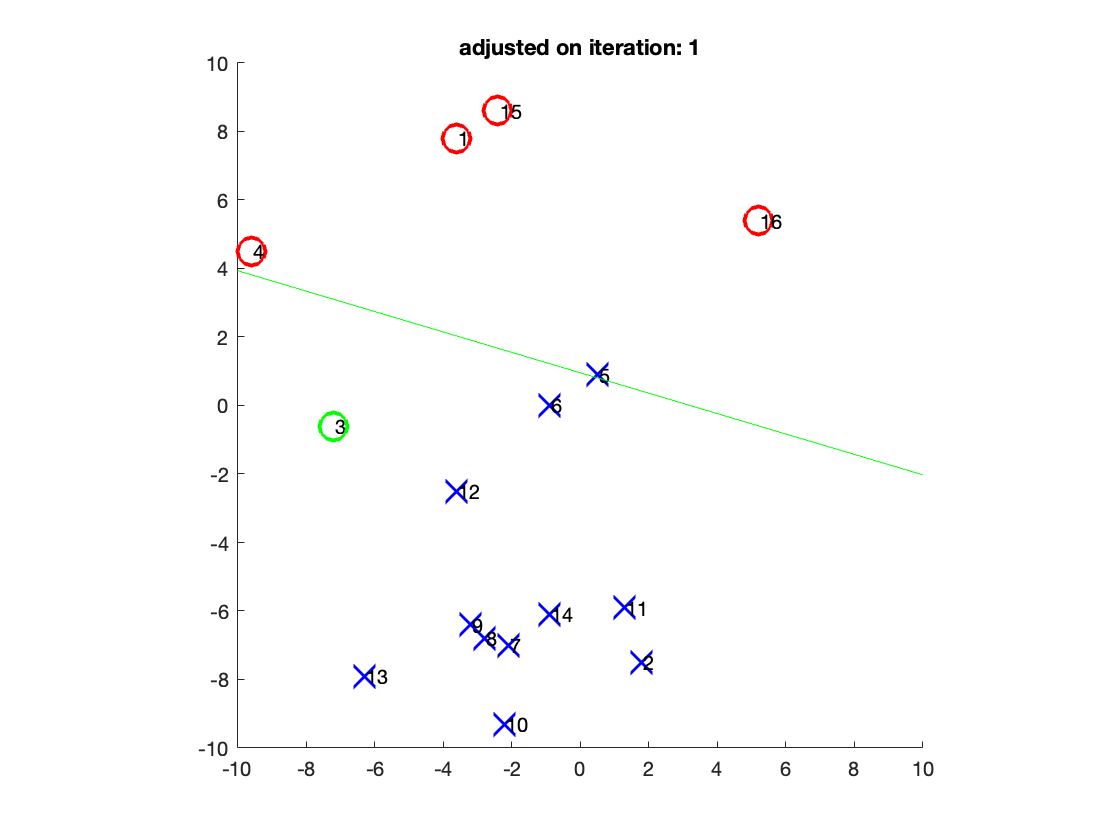

 testing data X(:,5)=[0.50,0.90]; y'=0.0646051; sign(y')=1, sign(y(i))=-1


adjusted from w=[0.21,0.71]; theta=0.68; to w=[0.16,0.61]; theta=0.77


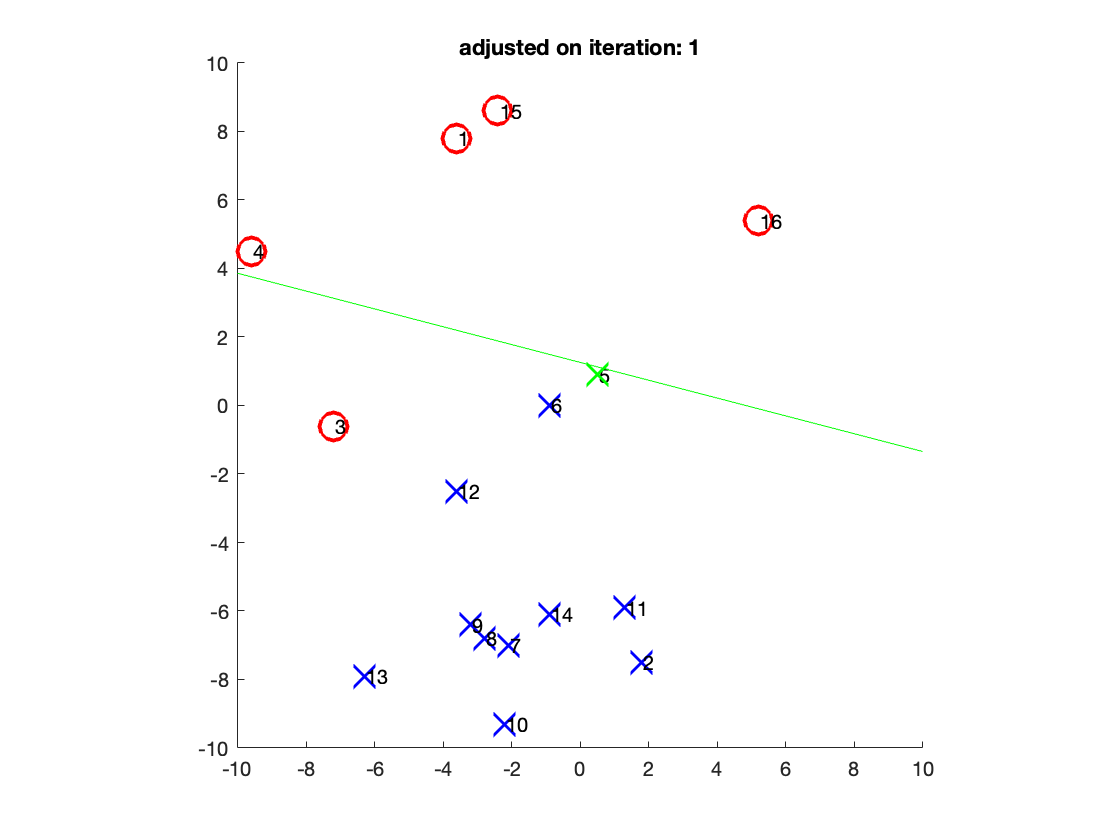

 testing data X(:,3)=[-7.20,-0.60]; y'=-2.29147; sign(y')=-1, sign(y(i))=1


adjusted from w=[0.16,0.61]; theta=0.77; to w=[-0.54,0.53]; theta=0.65


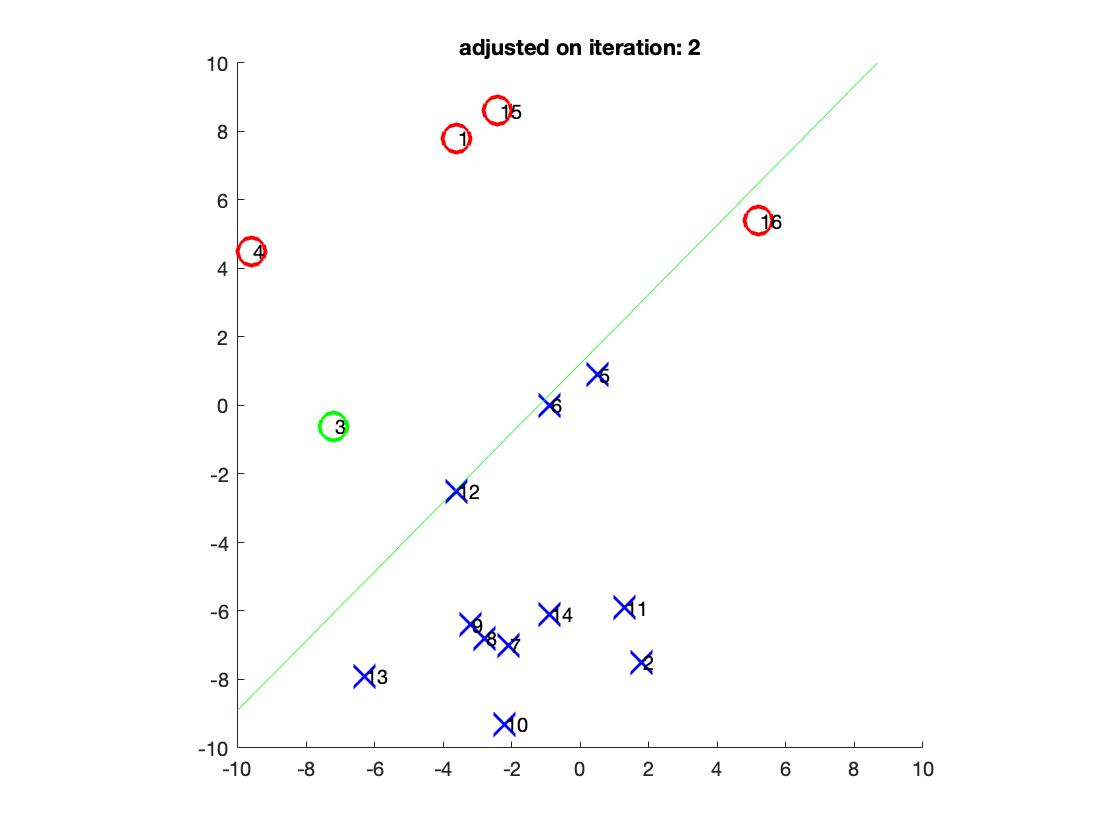

 testing data X(:,16)=[5.20,5.40]; y'=-0.575219; sign(y')=-1, sign(y(i))=1


adjusted from w=[-0.54,0.53]; theta=0.65; to w=[-0.017,0.89]; theta=0.46


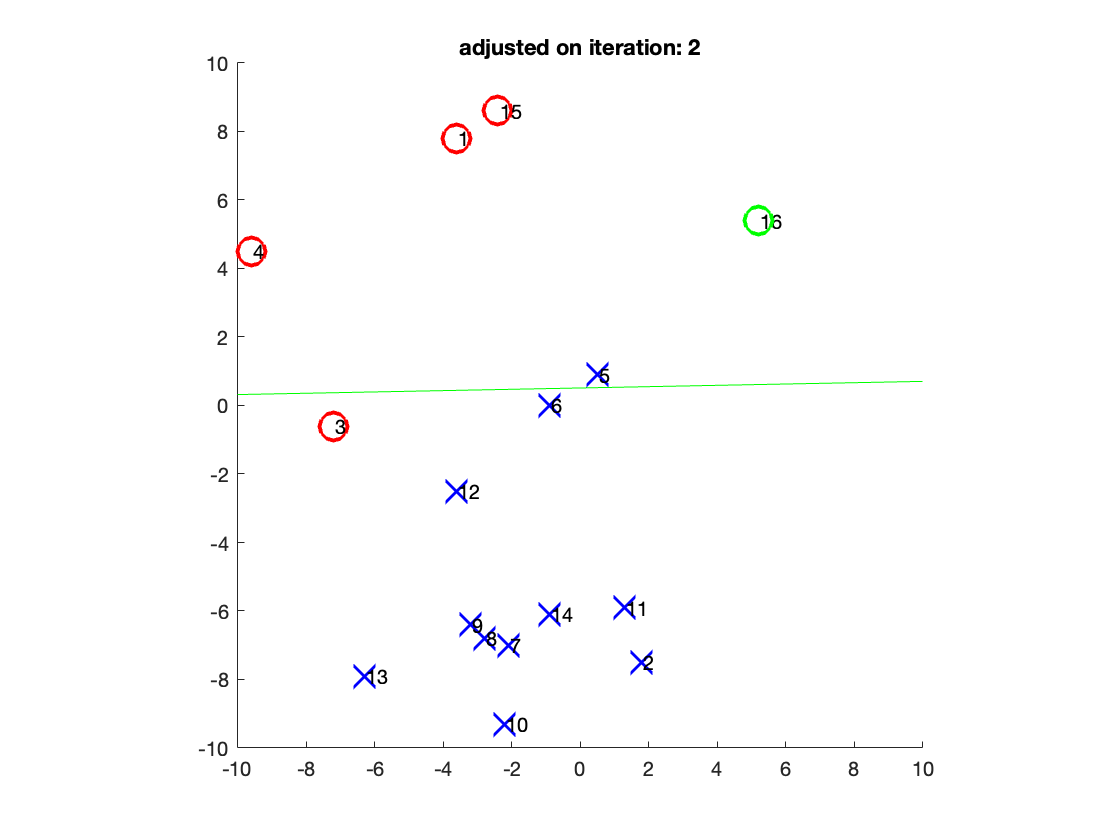

 testing data X(:,3)=[-7.20,-0.60]; y'=-0.865972; sign(y')=-1, sign(y(i))=1


adjusted from w=[-0.017,0.89]; theta=0.46; to w=[-0.63,0.71]; theta= 0.3


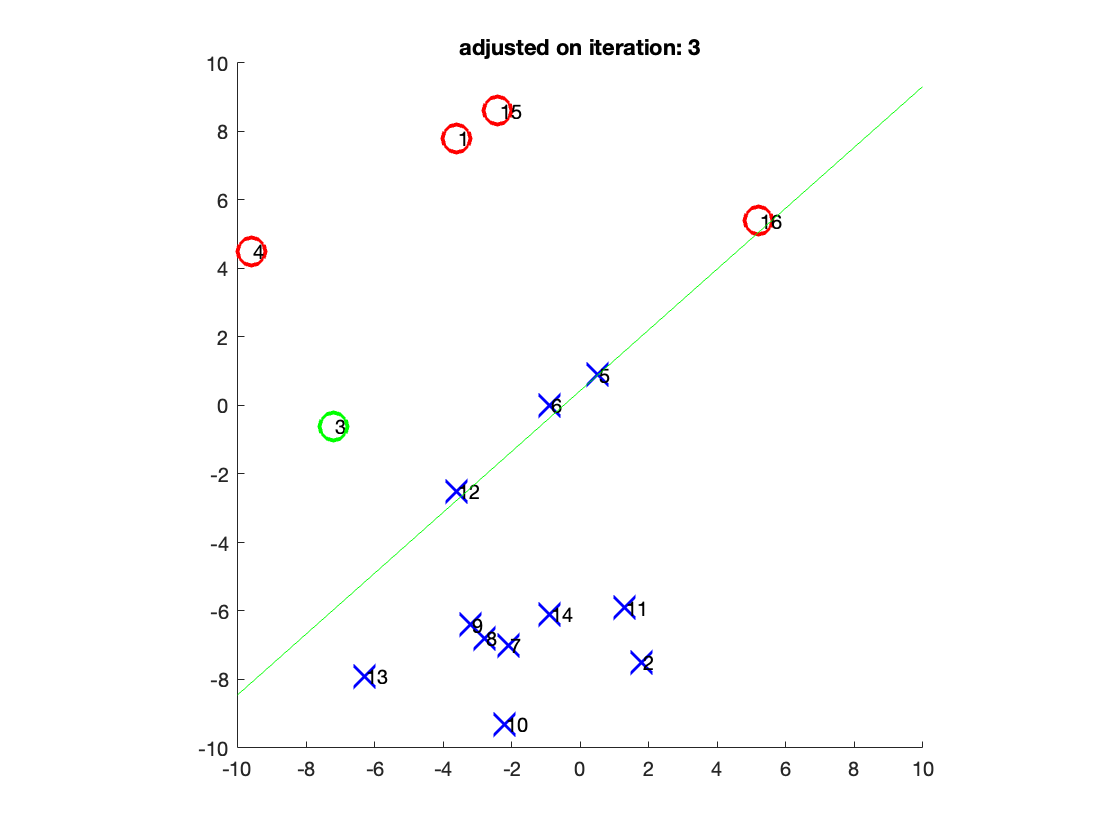

 testing data X(:,5)=[0.50,0.90]; y'=0.0199161; sign(y')=1, sign(y(i))=-1


adjusted from w=[-0.63,0.71]; theta=0.30; to w=[-0.68,0.62]; theta= 0.4


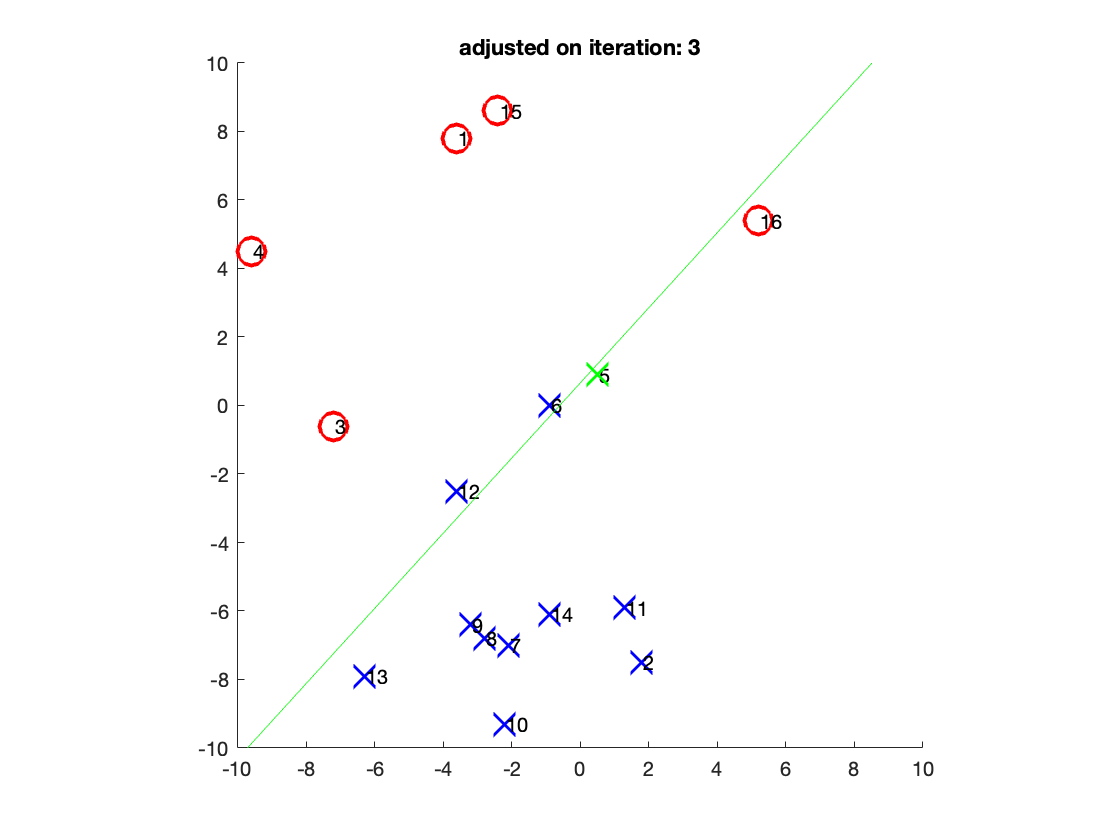

 testing data X(:,6)=[-0.90,0.00]; y'=0.207581; sign(y')=1, sign(y(i))=-1


adjusted from w=[-0.68,0.62]; theta=0.40; to w=[-0.59,0.62]; theta=0.51


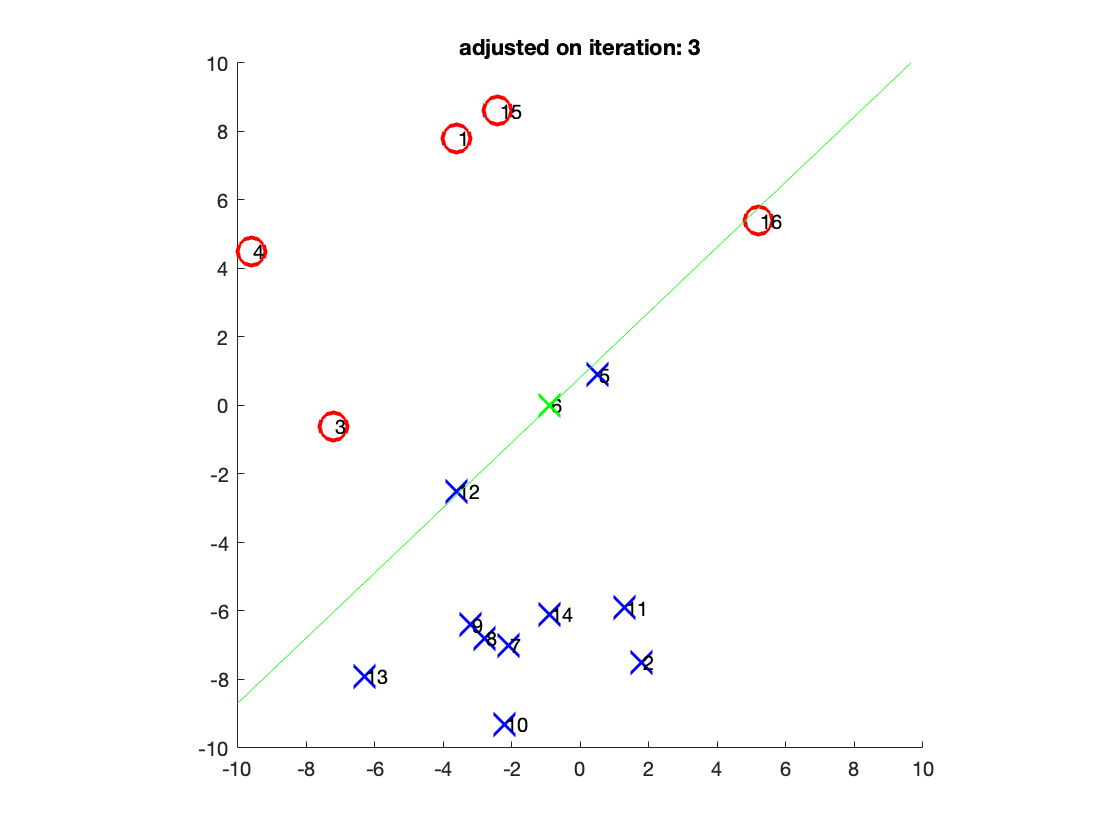

 testing data X(:,12)=[-3.60,-2.50]; y'=0.0690554; sign(y')=1, sign(y(i))=-1


adjusted from w=[-0.59,0.62]; theta=0.51; to w=[-0.21, 0.8]; theta=0.56


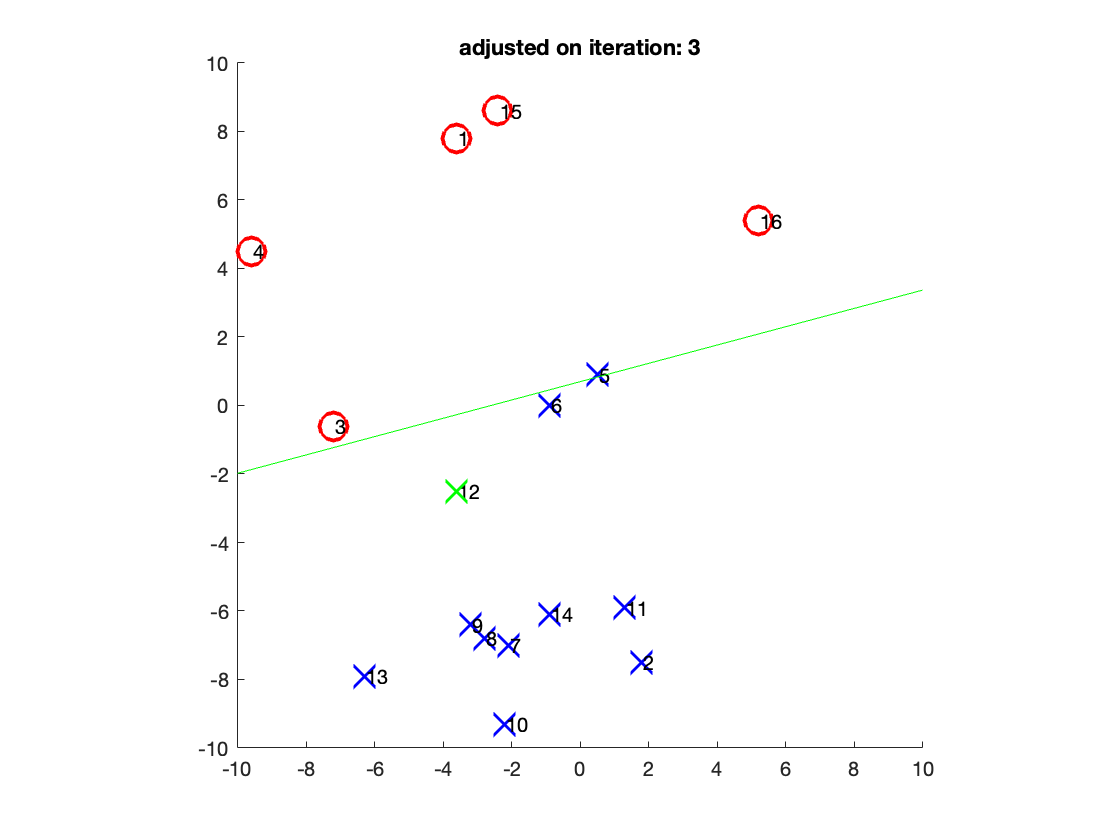

 testing data X(:,5)=[0.50,0.90]; y'=0.0574158; sign(y')=1, sign(y(i))=-1


adjusted from w=[-0.21, 0.8]; theta=0.56; to w=[-0.26,0.71]; theta=0.65


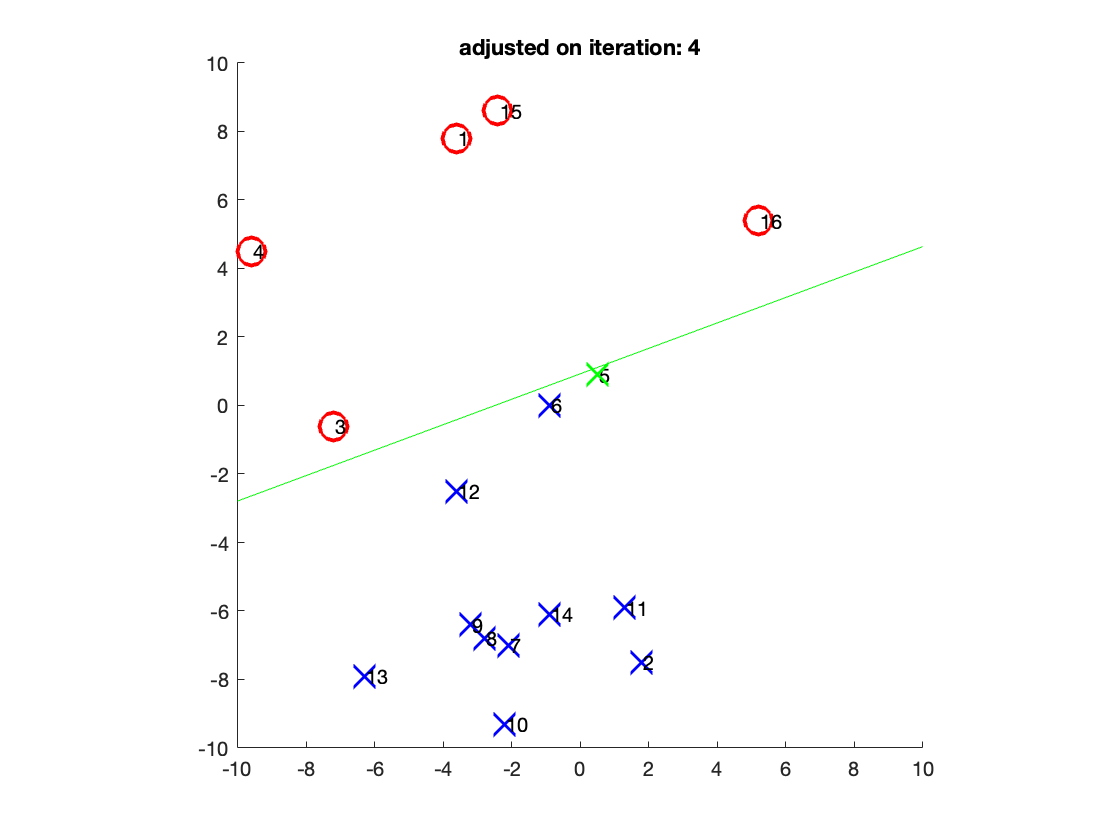

for epoch=1:1:num_epochs
for i=1:1:N
    % label the current datapoint
    yp=w'*[X(:,i);-1];
    
    if sign(yp) ~= sign(y(i))  || sign(yp)==0
        % adjustment step:
        w_old=w;
        theta_old=theta;
        w=w+eta*y(i)*[X(:,i);-1];
        
        % normalize to order 1. is this a good idea? sure
        w=w/norm(w);
        theta=w(dim+1);
        fprintf(1,' testing data X(:,%d)=[%4.2f,%4.2f]; y''=%g; sign(y'')=%d, sign(y(i))=%d\n' ...
                ,i,X(:,i),yp,sign(yp),sign(y(i)))
        fprintf(1,'adjusted from w=[%4.2g,%4.2g]; theta=%4.2f; to w=[%4.2g,%4.2g]; theta=%4.2g\n' ...
                ,w_old(1:dim),theta_old,w(1:dim),theta);
    
        % replot data for this iteration bc adjusted:
        figure;clf;hold on; title(['adjusted on iteration: ' num2str(epoch)])
        for j=1:1:N
          plot(X(1,j),X(2,j),[col(j) sym(j)],'markersize',14,'linewidth',2);
          if N<=30; text(X(1,j)+0.05,X(2,j),num2str(j)); end
        end
        xlim([-10 10]);ylim([-10 10]);
        axis square
        % draw currently considered data point in green:
        h_red_symbol=plot(X(1,i),X(2,i),['g' sym(i)],'markersize',14,'linewidth',2);
        % plot current preceptron-derived separation line
        if w(2) ~= 0
          hl=plot(line_lim,(theta-line_lim*w(1))/w(2),'g-');
        elseif w(1) ~= 0
          hl=plot((theta-line_lim*w(2))/w(1),line_lim,'g-');
        end
        hold off
        
    end
end
end

Show final w:

w

w =    -0.2633
    0.7089
    0.6543


## 2

clear all
load nonlin-percept-HW.mat
% (data, labels) XX; y and initial guess for w

u=XX(1,:);v=XX(2,:);

Adapted from "perceptron_nonlinear_classification_example.m"

Parameters:

% number of data points
[dim,N]=size(XX);
% number of epochs (passes over all data points)
Nepochs=20;
% base rate of adjustment of perceptron coefficients:
eta=0.01;
% nonlinear equation
eqn_X = [u; v; u.^2; u.*v; ones([1 N])];

Initial plot:

**Note: auxiliary field contour plotting function at the bottom of hw**

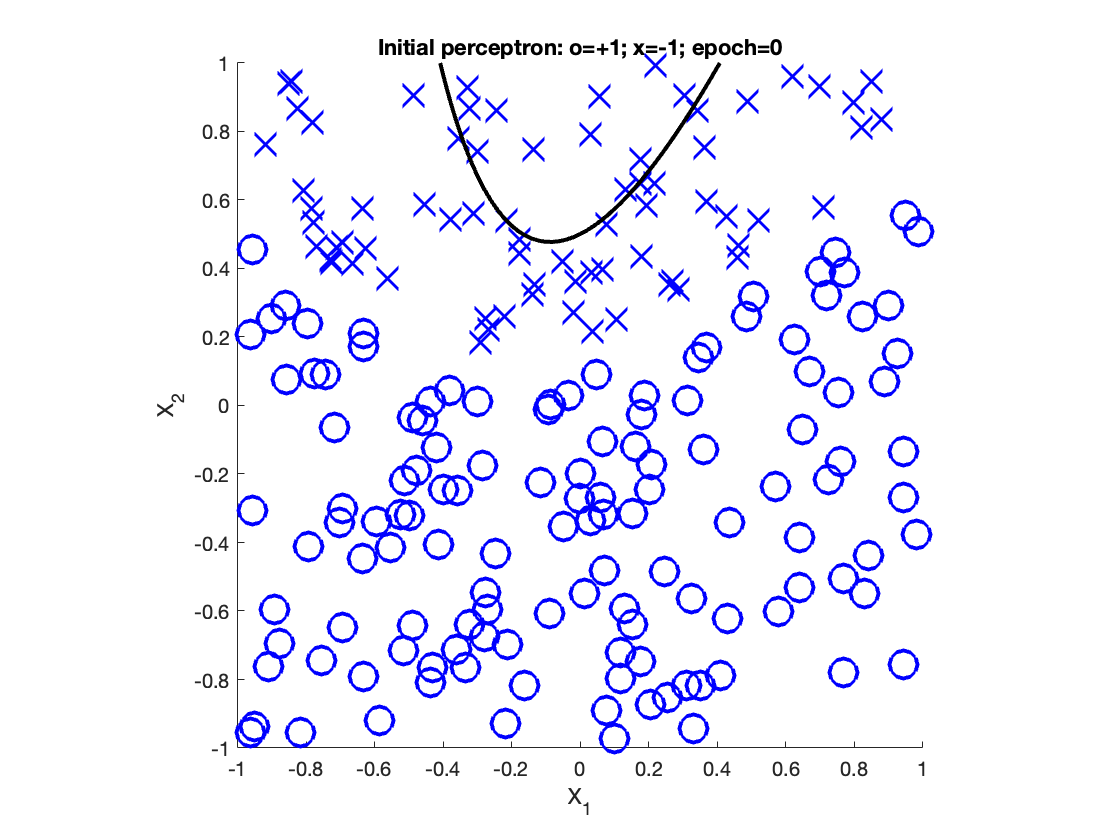

% x,y values to use only for plotting perceptron lines, no need to change:
xx=[-1:0.02:1]; yy=[-1:0.02:1];
Nx=length(xx); Ny=length(yy);

% plot training data:
sym(1:N)='o';
sym(y<0)='x';
figure;clf; hold on
for i=1:1:N
  plot(XX(1,i),XX(2,i),['b' sym(i)],'markersize',14,'linewidth',2);
  if N<=30; text(XX(1,i)+0.05,XX(2,i),num2str(i)); end
end
xlim([-1 1]);ylim([-1 1]);
axis square

% plot initial separation line as the zero contour level:
field=calc_perceptron_contour(w,xx,yy,Nx,Ny);
[hl,hc]=contour(xx,yy,field',[0,1000],'linewidth',2,'color','k');
xlabel('X_1');
ylabel('X_2');
epoch=0;
title(sprintf('Initial perceptron: o=+1; x=-1; epoch=%d',epoch));
hold off

Training/learning loop:

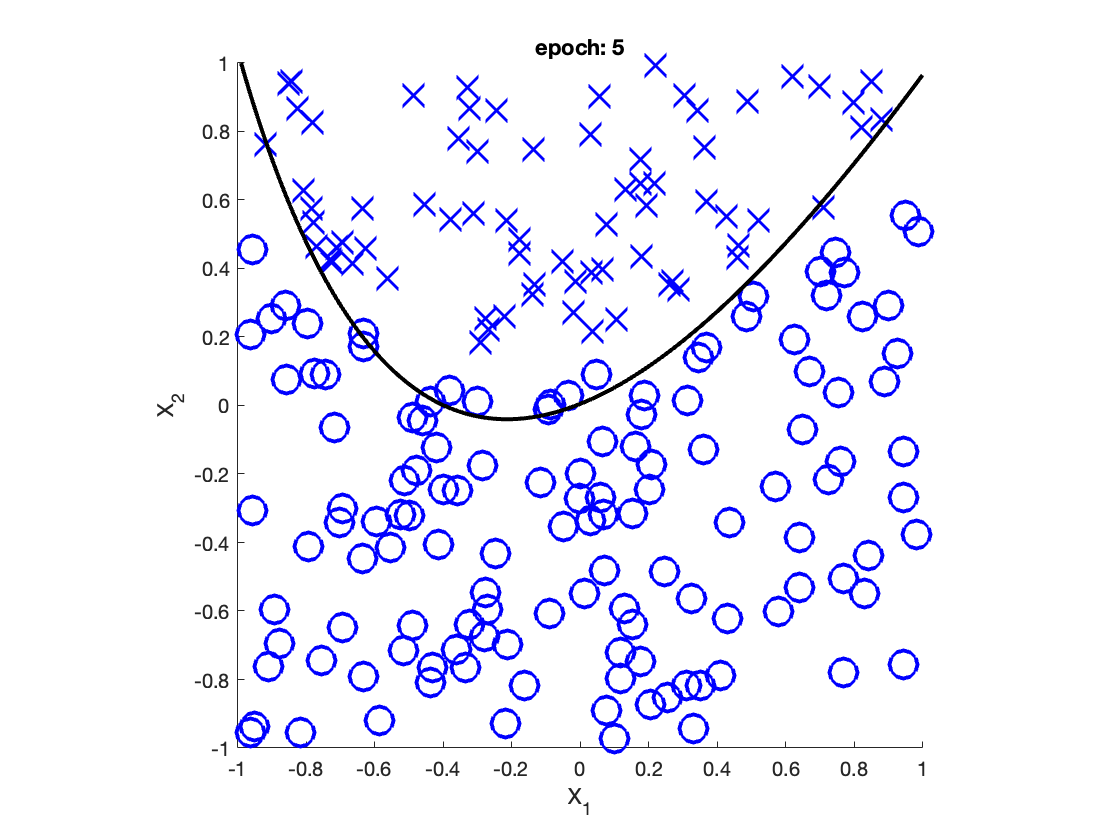

for epoch=1:1:Nepochs
for i=1:1:N
    % label the current data point:
    yp=w'*eqn_X(:,i);
    if sign(yp) ~= sign(y(i))  || sign(yp)==0
        % adjustment step:
        w_old=w;
        w=w+(eta*y(i)*eqn_X(:,i));
        
        % normalize to order 1. is this a good idea? sure
        w=w/norm(w);
    end
end

    % re-plot after every 5 epochs:
    if ~mod(epoch,5)
        figure; hold on
        for j=1:1:N
          plot(XX(1,j),XX(2,j),['b' sym(j)],'markersize',14,'linewidth',2);
        end
        xlim([-1 1]);ylim([-1 1]);
        axis square
        xlabel('X_1');
        ylabel('X_2');
        title(['epoch: ' num2str(epoch)]);
        
        % plot new separation line:
        field=calc_perceptron_contour(w,xx,yy,Nx,Ny);
        [hl,hc]=contour(xx,yy,field',[0,1000],'linewidth',2,'color','k');
        hold off
    end
end

Show final w:

w

w =     0.2431
   -0.7088
    0.5923
   -0.2914
    0.0530


## 3

clear all
w2=[-0.31314, 0.38796;
-0.60718, 0.67412;
2.8908, -1.5217];
b2=[ 0.81989;
0.81574;
3.674];
w3=[ -1.007, -1.7446, 5.1881;
16.877, -7.3917, -4.1027;
50.772, -21.437, -38.171];
b3=[-15.236;
-1.8673;
20.628];
w4=[ 1.812, 44.299, -35.869];
b4=[ 5.2558];

Some activation functions:

sigmoid = @(x) 1.0./(1.0+exp(-x));
linear = @(x) x;

Input space:

x1=1:0.1:2;
x2=1:0.1:2;

3a)

[pic of drawing]

3b)

[pic of hand calc]

3c)

Look at sizes needed for input and output layers:

disp('input:')
size(w2)
disp('output:')
size(w4)

So looks like inputs to be column vectors, output will be 1 dim

inputs:

disp('10 inputs:')
X=[1:0.1:1.9;...
    1:0.01:1.09]

Neural network:

a2 = sigmoid(w2*X + b2);
a3 = sigmoid(w3*a2 + b3);
a4 = linear(w4*a3 + b4);

disp('10 outputs:')
outputs = a4

**Deduce which simple function of the inputs x1; x2 the network returns.**

Look at 3D surface plot of neural network output:

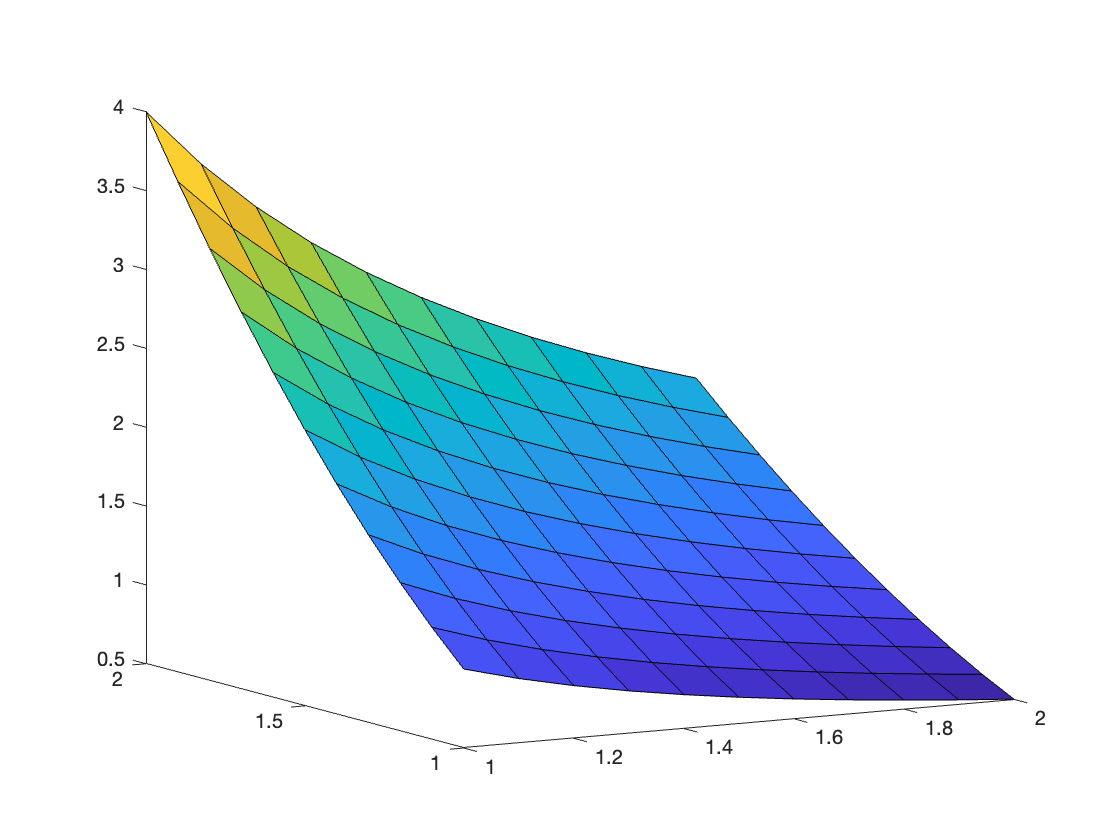

x1=1:0.1:2;
x2=1:0.1:2;
[X1, X2]=meshgrid(x1, x2);

a2 = sigmoid(w2*[X1(:).'; X2(:).'] + b2);
a3 = sigmoid(w3*a2 + b3);
a4 = linear(w4*a3 + b4);

A = a4;
figure; hold on
surf(X1, X2, reshape(A, size(X1)) )
view(-30,10)
hold off

From hovering mouse over various points, it looks like points change 1) directly proportional to 1/x_1 as we keep x_2 constant and 2) x_2^2 when x_1 is constant. So looks like it's approximating: $\frac{x_2^2}{x_1}$

**Don't you think it's amazing that this actually works? :-) **Yeah

**Does it also work for the input [-0.5;3.5]?**

test_x = [-0.5;3.5]

a2 = sigmoid(w2*test_x + b2);
a3 = sigmoid(w3*a2 + b3);
a4 = linear(w4*a3 + b4);

nn_output = a4

nn_output = 13.5935


actual_output = test_x(2,1).^2 ./ test_x(1,1)

actual_output = -24.5000

No

**Can you guess why?** Maybe neural network hasn't been trained to distinguish/can not generalize past this asymptote because this is pretty different and hard to predict from just looking at a tiny, non-asymptotic and fairly smooth section of the general function.

Check by extending my output surface plot past x_1=0:

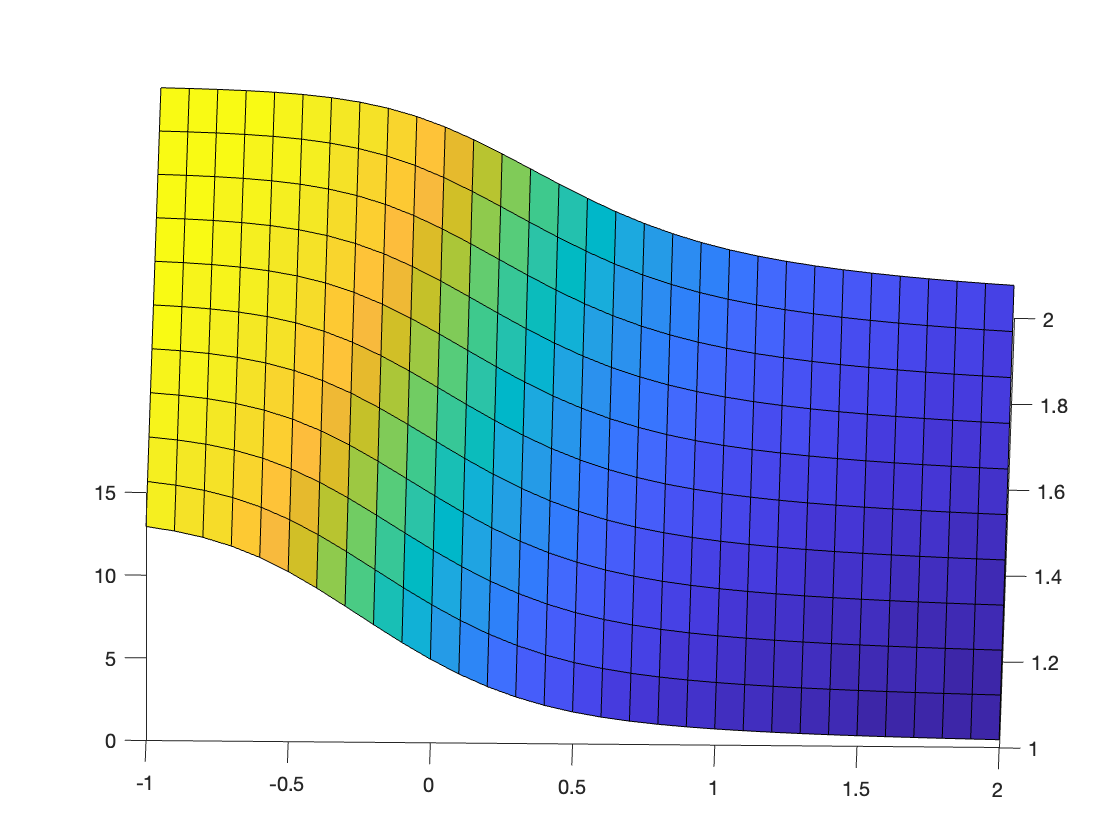

x1=-1:0.1:2;
x2=1:0.1:2;
[X1, X2]=meshgrid(x1, x2);

a2 = sigmoid(w2*[X1(:).'; X2(:).'] + b2);
a3 = sigmoid(w3*a2 + b3);
a4 = linear(w4*a3 + b4);

A = a4;
figure; hold on
surf(X1, X2, reshape(A, size(X1)) )
view([1 60])
hold off

NN is smooth all the way through x_1=0.

Auxillary functions:

function field=calc_perceptron_contour(w,xx,yy,Nx,Ny)
for i=1:Nx; for j=1:Ny
  field(i,j)=w(1)*xx(i)+w(2)*yy(j)+w(3)*xx(i)^2+w(4)*xx(i)*yy(j)+w(5);
end; end
end